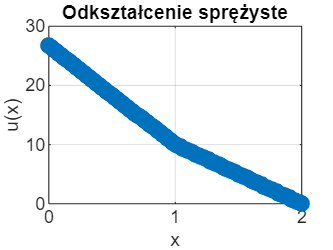

n = input('Input n: ');
[B, L] = fill_mat(n);
solution = [B \ L; 0];
x = linspace(0, 2, n + 1);
y = zeros(1, n+1);
for i=0:length(x)-1
    for j=0:length(solution)-1
        y(i+1) = y(i+1) + solution(j+1) * base_f(n,j, x(i+1));
    end
end

plot(x, y, '-o', 'LineWidth', 2);
title('Odkształcenie sprężyste');
xlabel('x');
ylabel('u(x)');
grid on;